function P = newton_interpolation(x, divided_diff, x_interp)
    n = length(x);
    P = divided_diff(1,1);
    term = 1;

    for j = 2:n
        term = term * (x_interp - x(j-1));
        P = P + term * divided_diff(1,j);
    end
end

x = [1, 1.5, 2, 3, 4];
y = [0, 0.17609, 0.30103, 0.47712, 0.60206];

n = length(x);
divided_diff = zeros(n, n);
divided_diff(:,1) = y';

for j = 2:n
    for i = 1:n-j+1
        divided_diff(i,j) = (divided_diff(i+1,j-1) - divided_diff(i,j-1)) / (x(i+j-1) - x(i));
    end
end

disp(divided_diff);

         0    0.3522   -0.1023    0.0266   -0.0057
    0.1761    0.2499   -0.0492    0.0094         0
    0.3010    0.1761   -0.0256         0         0
    0.4771    0.1249         0         0         0
    0.6021         0         0         0         0



lg_2_5 = newton_interpolation(x, divided_diff, 2.5);
lg_3_25 = newton_interpolation(x, divided_diff, 3.25);

disp(['Approximate lg(2.5): ', num2str(lg_2_5)]);

Approximate lg(2.5): 0.39687


disp(['Approximate lg(3.25): ', num2str(lg_3_25)]);

Approximate lg(3.25): 0.51327


yi = (10:35) / 10; 
true_values = log10(yi); 
interp_values = arrayfun(@(v) newton_interpolation(x, divided_diff, v), yi);
error = max(abs(true_values - interp_values));

disp(['Maximum interpolation error: ', num2str(error)]);

Maximum interpolation error: 0.0026495


yi = (10:35) / 10; 
true_values = log10(yi); 


interp_values = zeros(size(yi));
for i = 1:length(yi)
    interp_values(i) = newton_interpolation(x, divided_diff, yi(i));
end

error = max(abs(true_values - interp_values));

disp(['Maximum interpolation error: ', num2str(error)]);

Maximum interpolation error: 0.0026495


x = [1, 2, 3, 4, 5];
y = [22, 23, 25, 30, 28];

n = length(x);
divided_diff = zeros(n, n);
divided_diff(:,1) = y';

for j = 2:n
    for i = 1:n-j+1
        divided_diff(i,j) = (divided_diff(i+1,j-1) - divided_diff(i,j-1)) / (x(i+j-1) - x(i));
    end
end
disp(divided_diff);

   22.0000    1.0000    0.5000    0.3333   -0.5000
   23.0000    2.0000    1.5000   -1.6667         0
   25.0000    5.0000   -3.5000         0         0
   30.0000   -2.0000         0         0         0
   28.0000         0         0         0         0



yield_2_5 = newton_interpolation(x, divided_diff, 2.5);
disp(['Estimated potato yield for 2.5 lbs fertilizer: ', num2str(yield_2_5)]);

Estimated potato yield for 2.5 lbs fertilizer: 23.4688


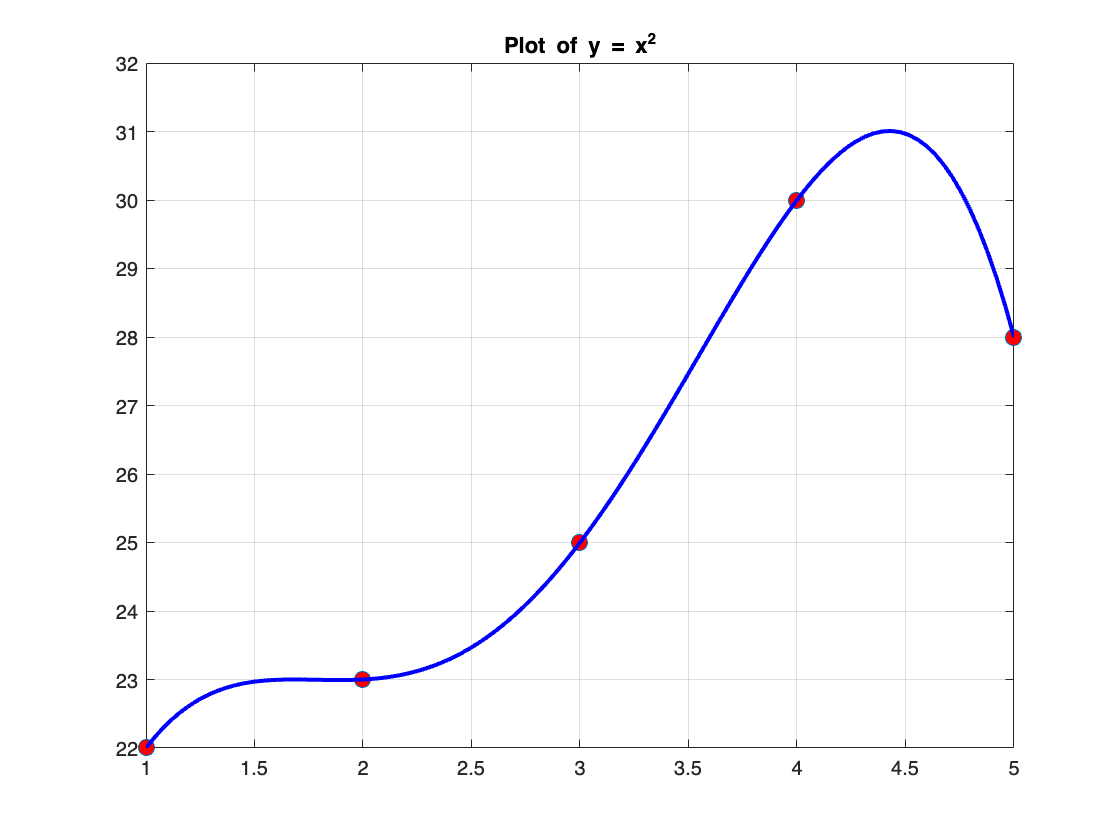

x_plot = linspace(1, 5, 100);
y_interp = zeros(size(x_plot));

for i = 1:length(x_plot)
    y_interp(i) = newton_interpolation(x, divided_diff, x_plot(i));
end

figure;
plot(x, y, 'o', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
hold on;
plot(x_plot, y_interp, 'b', 'LineWidth', 2);
grid on;
hold off;

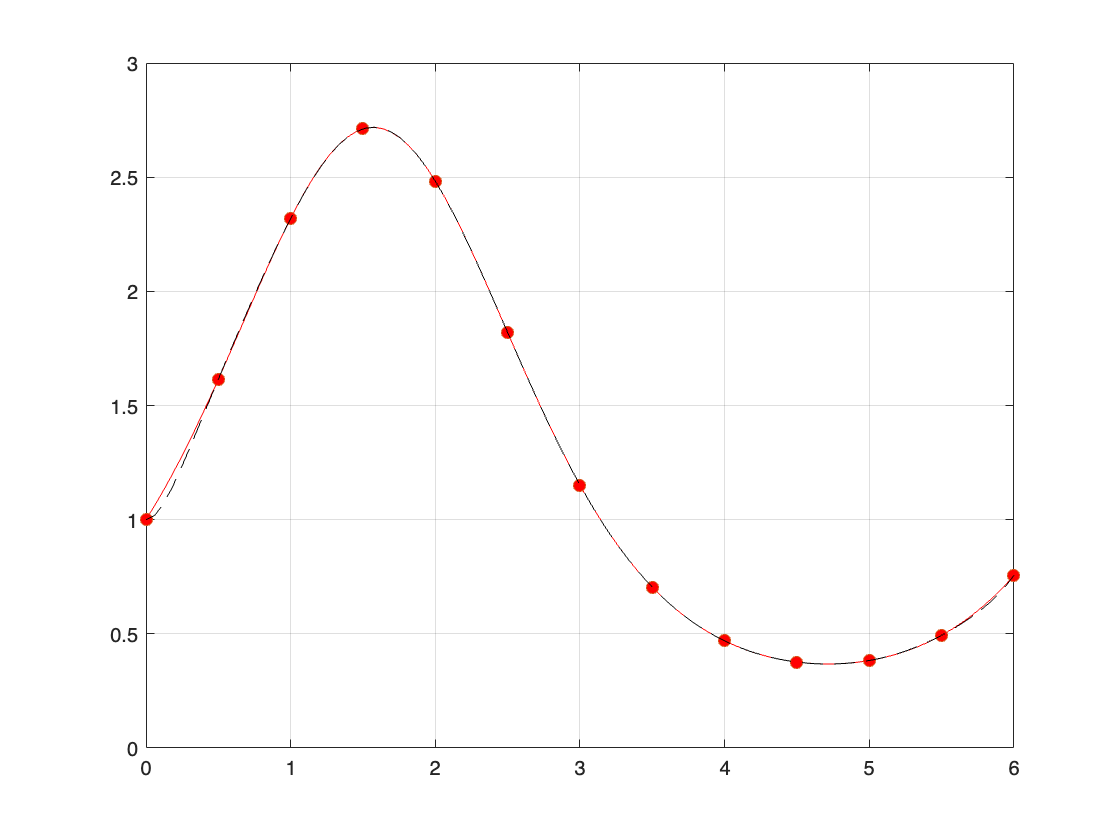

f = @(x) exp(sin(x));

x_nodes = linspace(0, 6, 13);
y_nodes = f(x_nodes);

n = length(x_nodes);
divided_diff = zeros(n, n);
divided_diff(:,1) = y_nodes';

for j = 2:n
    for i = 1:n-j+1
        divided_diff(i,j) = (divided_diff(i+1,j-1) - divided_diff(i,j-1)) / (x_nodes(i+j-1) - x_nodes(i));
    end
end

x_test = linspace(0, 6, 100);
y_true = f(x_test);
y_interp = zeros(size(x_test)); 

for i = 1:length(x_test)
    y_interp(i) = newton_interpolation(x_nodes, divided_diff, x_test(i));
end

figure;
plot(x_test, y_true, 'r'); % Function f(x)
hold on;
plot(x_nodes, y_nodes, 'o', 'MarkerFaceColor', 'r'); % Interpolation points
plot(x_test, y_interp, 'k--'); % Newton interpolation polynomial
grid on;
hold off;

N = 115;
epsilon = 1e-3;

P = zeros(100, 100);
P(1,1) = 10;  
P(2,1) = 11;  

i = 2;

while true
    P(i+1,1) = (P(i,1) + P(i-1,1)) / 2; 

    if i > 1
        num = (P(i+1,1) - P(i,1)) * P(i-1,1) - (P(i,1) - P(i-1,1)) * P(i+1,1); % Aitken’s Acceleration Formula
        den = P(i+1,1) - 2*P(i,1) + P(i-1,1);
        P(i,2) = num / den;
        
        if abs(P(i,2) - P(i-1,2)) < epsilon
            break;
        end
    end
    
    i = i + 1;
end

disp('Aitken’s Table (Partial Display for Convergence Steps):');

Aitken’s Table (Partial Display for Convergence Steps):


disp(P(1:i,1:2)); 

   10.0000         0
   11.0000   10.3333
   10.5000   10.8333
   10.7500   10.5833
   10.6250   10.7083
   10.6875   10.6458
   10.6562   10.6771
   10.6719   10.6615
   10.6641   10.6693
   10.6680   10.6654
   10.6660   10.6673
   10.6670   10.6663



disp(['Approximated sqrt(115): ', num2str(P(i,2))]);

Approximated sqrt(115): 10.6663


disp(['Actual sqrt(115): ', num2str(sqrt(115))]);

Actual sqrt(115): 10.7238


function P = neville(x_nodes, y_nodes, x_interp)
    n = length(x_nodes);
    P = zeros(n, n); 
    P(:,1) = y_nodes'; 

    for j = 2:n
        for i = 1:(n-j+1)
            P(i,j) = ((x_interp - x_nodes(i)) * P(i+1,j-1) - (x_interp - x_nodes(i+j-1)) * P(i,j-1)) / (x_nodes(i+j-1) - x_nodes(i));
        end
    end
    
    P = P(1,n); 
end

% (a)
x_nodes_a = [-2, -1, 0, 1, 2];
y_nodes_a = 3.^x_nodes_a;
x_interp = sqrt(3);

P_a = neville(x_nodes_a, y_nodes_a, 1/2);
disp(['Neville interpolation for f1(x) at sqrt(3): ', num2str(P_a)]);

Neville interpolation for f1(x) at sqrt(3): 1.7083


% (b)
x_nodes_b = [0, 1, 2, 4, 5];
y_nodes_b = sqrt(x_nodes_b);

P_b = neville(x_nodes_b, y_nodes_b, 3);
disp(['Neville interpolation for f2(x) at sqrt(3): ', num2str(P_b)]);

Neville interpolation for f2(x) at sqrt(3): 1.6906
